# **Trajectories Generation -- Merbouche Mouloud**

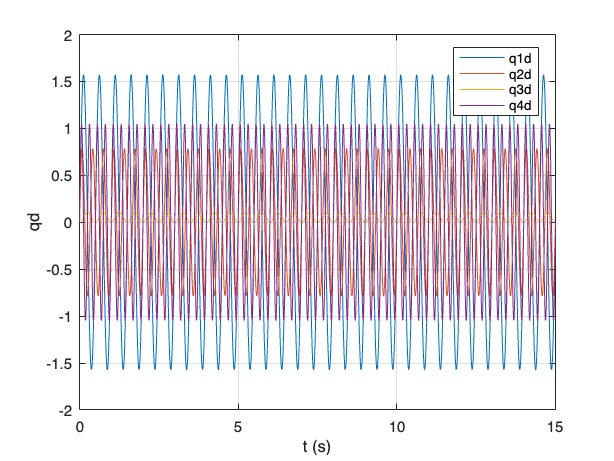

clear; 
close all; 
clc

t0 = 0;
tf = 15;
dt = 0.001;
t  = t0:dt:tf;

q1d = (pi/2) * sin(4*pi*t);
q2d = (pi/4) * sin(6*pi*t);
q3d = 0.1    * (sin(2*pi*t)).^2;
q4d = (pi/3) * sin(8*pi*t);

qd = [q1d; q2d; q3d; q4d];

dqd  = zeros(size(qd));
ddqd = zeros(size(qd));

for i = 1:4
    dqd(i,:)  = derive(t, qd(i,:));
    ddqd(i,:) = derive(t, dqd(i,:));
end


d = [ 0 ; 0.22 ; 0.24 ; 0 ];
alph = [ 0 ; 0 ; 0 ; 0 ] ;
r = [ 0 ; 0 ; 0 ; 0 ] ;
th = [ 0 ; 0 ; 0 ; 0 ] ;

N = length(t);

Xd = zeros(3, N);
n = 4;

for nn = 1:N

    th(1) = q1d(nn);
    th(2) = q2d(nn);
    r(3)  = q3d(nn);
    th(4) = q4d(nn);

    for k = 1:n
        T(:,:,k) = [ cos(th(k))               , -sin(th(k))               , 0 , d(k) ;
                     cos(alph(k))*sin(th(k))  ,  cos(alph(k))*cos(th(k))  , -sin(alph(k)) , -r(k)*sin(alph(k)) ;
                     sin(alph(k))*sin(th(k))  ,  sin(alph(k))*cos(th(k))  ,  cos(alph(k)) ,  r(k)*cos(alph(k)) ;
                     0                        ,  0                        , 0 , 1 ];
    end

    T40 = T(:,:,1) * T(:,:,2) * T(:,:,3) * T(:,:,4);

    Xd(:,nn) = T40(1:3,4);
end

dXd  = zeros(size(Xd));
ddXd = zeros(size(Xd));

for i = 1:3
    dXd(i,:)  = derive(t, Xd(i,:));
    ddXd(i,:) = derive(t, dXd(i,:));
end


figure('Name','Desired joint positions qd');
plot(t, qd'); grid on
xlabel('t (s)'); ylabel('qd');
legend('q1d','q2d','q3d','q4d','Location','best');

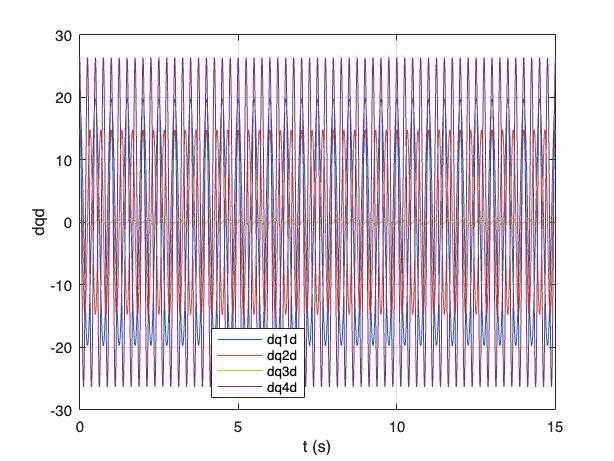


figure('Name','Desired joint velocities dqd');
plot(t, dqd'); grid on
xlabel('t (s)'); ylabel('dqd');
legend('dq1d','dq2d','dq3d','dq4d','Location','best');

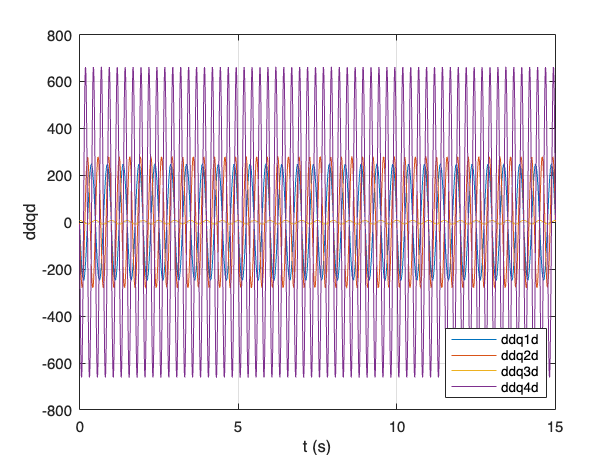


figure('Name','Desired joint accelerations ddqd');
plot(t, ddqd'); grid on
xlabel('t (s)'); ylabel('ddqd');
legend('ddq1d','ddq2d','ddq3d','ddq4d','Location','best');

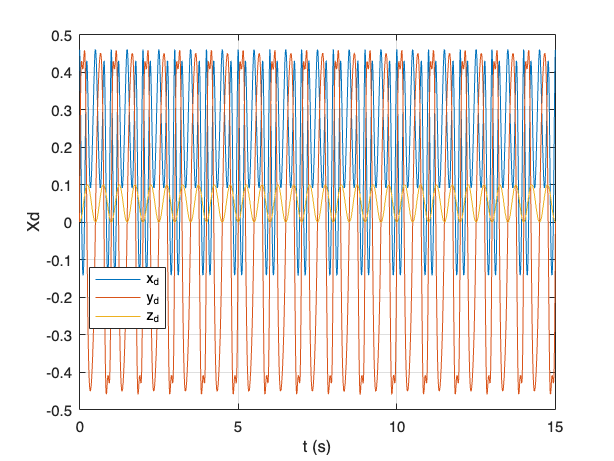


% Plots (Xd, dXd, ddXd)
figure('Name','Desired end-effector position Xd');
plot(t, Xd'); grid on
xlabel('t (s)'); ylabel('Xd');
legend('x_d','y_d','z_d','Location','best');

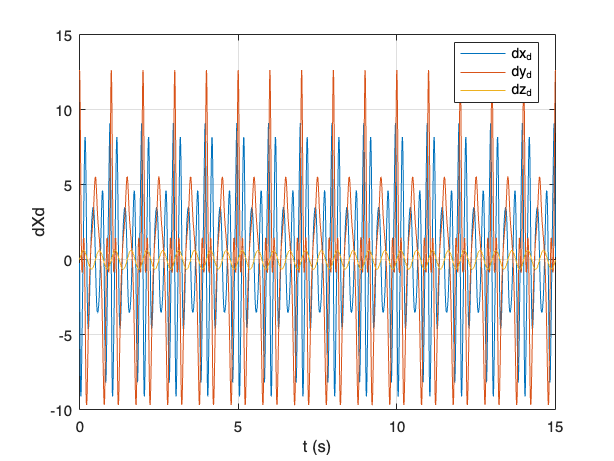


figure('Name','Desired end-effector velocity dXd');
plot(t, dXd'); grid on
xlabel('t (s)'); ylabel('dXd');
legend('dx_d','dy_d','dz_d','Location','best');

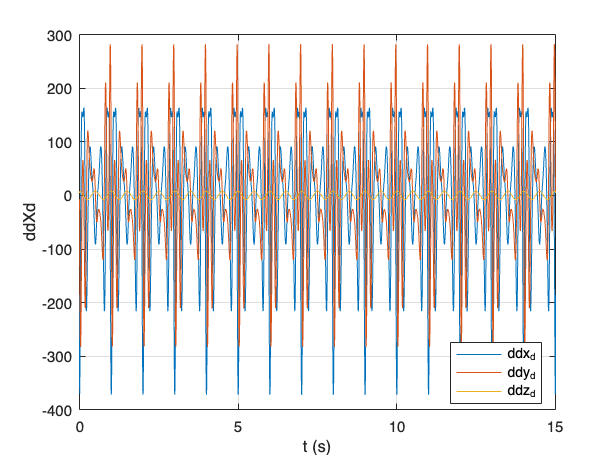


figure('Name','Desired end-effector acceleration ddXd');
plot(t, ddXd'); grid on
xlabel('t (s)'); ylabel('ddXd');
legend('ddx_d','ddy_d','ddz_d','Location','best');

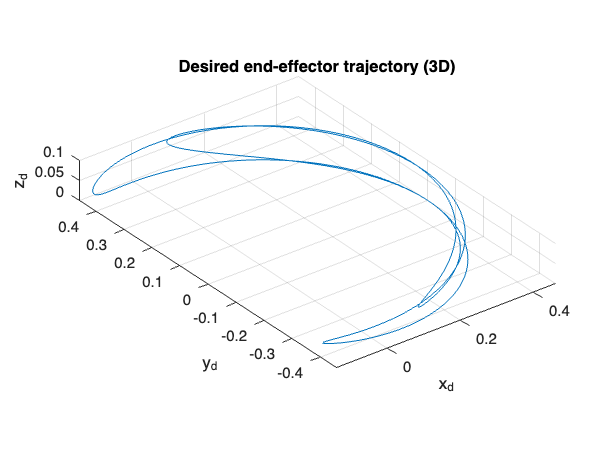


%3D plot of Xd
figure('Name','Xd in 3D');
plot3(Xd(1,:), Xd(2,:), Xd(3,:)); grid on; axis equal
xlabel('x_d'); ylabel('y_d'); zlabel('z_d');
title('Desired end-effector trajectory (3D)');


save('joint_traj.mat', 't', 'dt', 'qd', 'dqd', 'ddqd');
save('end_eff_traj.mat', 't', 'dt', 'Xd', 'dXd', 'ddXd');


% derive function
function df = derive(t, f)
    df = [ f(1,2) - f(1,1), ...
        (f(1,3:end) - f(1,1:end-2)) / 2, ...
        f(1,end) - f(1,end-1) ...
        ] / (t(1,2) - t(1,1));
end